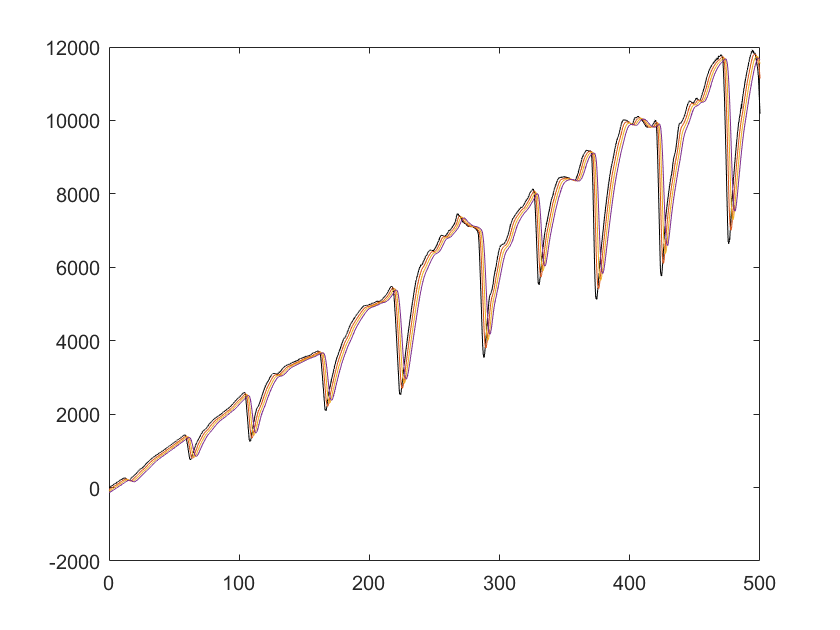

%% Simulate the car following model.
%It is similar to the way done in class.

clear; clc; % close all;

%% Set parameters
% number of simulated vehicles
veh_num=3;

% driver parameters (identical for each driver)
alpha=0.2;
beta=0.7;
tau=0.5;
l = 4.5;

% range policy parameters
vmax=30;
hst=5;
kappa=0.6;
hgo=hst+vmax/kappa;
% "linear" range policy
V=@(h)vmax*(hgo<=h) + kappa*(h-hst).*(hst<h & h<hgo);
% equilibrium speed and headway
vstar=20;
hstar=hst+vstar/kappa;

% select between open chain and ring configurations
vehconfig='chain';
% vehconfig='ring';

% time step for simulations
deltat=0.1;
% vector of time instants
t0=0;
tend=500;
time=t0:deltat:tend;

% %Importing External Data stored in 'v_lead_data.mat'
load('20170730_114049_8_vehicles','vel');
vLead = vel{1};
vLeadtau=(time<t0+tau).*vstar+...
              (t0+tau<=time).*interp1(time,vLead,time-tau,'linear','extrap');


% %% Prescribe leader velocity profile
% % open chain of vehicles
% if strcmp(vehconfig,'chain')
%     % piecewise linear function with following points
%     vL0=vstar; vL1=vstar-10; vL2=vstar; vLend=vstar; 
%     t1=10; t2=30;
%     % leader velocity values at these time instants
%     vLead=(t0<=time & time<t1).*(vL0+(vL1-vL0)/(t1-t0)*(time-t0))+...
%           (t1<=time & time<t2).*(vL1+(vL2-vL1)/(t2-t1)*(time-t1))+...
%           (t2<=time & time<=tend).*(vL2+(vLend-vL2)/(tend-t2)*(time-t2));
%     % delayed leader velocity values
%     vLeadtau=(time<t0+tau).*vstar+...
%              (t0+tau<=time).*interp1(time,vLead,time-tau,'linear','extrap');
% % no leader in ring configuration
% else
%     vLead=[];
%     vLeadtau=[];
% end
% sLead = vLead.*time;

%% Prescribe initial conditions
% initial velocity and headway of each vehicle of the open chain
if strcmp(vehconfig,'chain')
    v0=vstar*ones(1,veh_num);
    h0=hstar*ones(1,veh_num);
% initial velocity and headway of each vehicle of the ring
else
    vamp=5;
    kk=1;
    om=2*(alpha+beta)*tan(kk*pi/veh_num);
    v0=vstar+vamp*cos(2*kk*pi/veh_num*(1:veh_num));
    h0=hstar+vamp/om*(sin(2*kk*pi/veh_num*(2:veh_num+1))-...
                      sin(2*kk*pi/veh_num*(1:veh_num)));
end
% initial state as x0=[h_i(0); v_i(0); h_{i-1}(0); v_{i-1}(0); ...]
x0=[h0;v0]; x0=x0(:);
% initial function: constant initial state over the delay interval
f=@(t)x0;

%% Simulate optimal velocity model of car following
% perform simulation
sol=dde23(@(t,x,xtau)OVM(t,x,xtau,time,vLead,vLeadtau,alpha,beta,V),...
            tau,f,[time(1) time(end)]);
xsol=deval(sol,time);
% extract headway and velocity from solution xsol=[h_i; v_i; h_{i-1}; v_{i-1}; ...]
hFollow=zeros(veh_num,length(time));
vFollow=zeros(size(hFollow));
sFollow=zeros(size(hFollow));
for kveh=1:veh_num
    hFollow(kveh,:)=xsol(2*kveh-1,:).';
    vFollow(kveh,:)=xsol(2*kveh,:).';
    sFollow(kveh,:)=  vFollow(kveh,:).*(time-tau) - kveh*l - kveh*hstar;
end
    
%% Plot simulated data

% plot position
figure(1); clf; hold on; box on;
plot(time,sLead,'-k');
plot(time,sFollow);

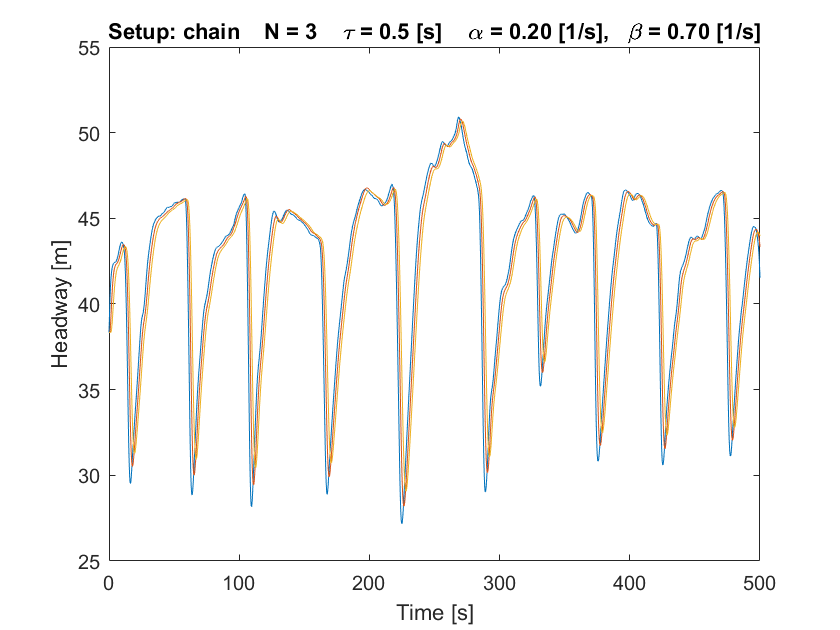


% plot headway
figure(2); clf; hold on; box on;
plot(time,hFollow);
xlabel('Time [s]');
ylabel('Headway [m]');
title(['Setup: ',vehconfig,'    N = ',num2str(veh_num),'    ',...
       '\tau = ',num2str(tau),' [s]    ',...
       '\alpha = ',num2str(alpha,'%3.2f'),' [1/s],   ',...
       '\beta = ',num2str(beta,'%3.2f'),' [1/s]']);

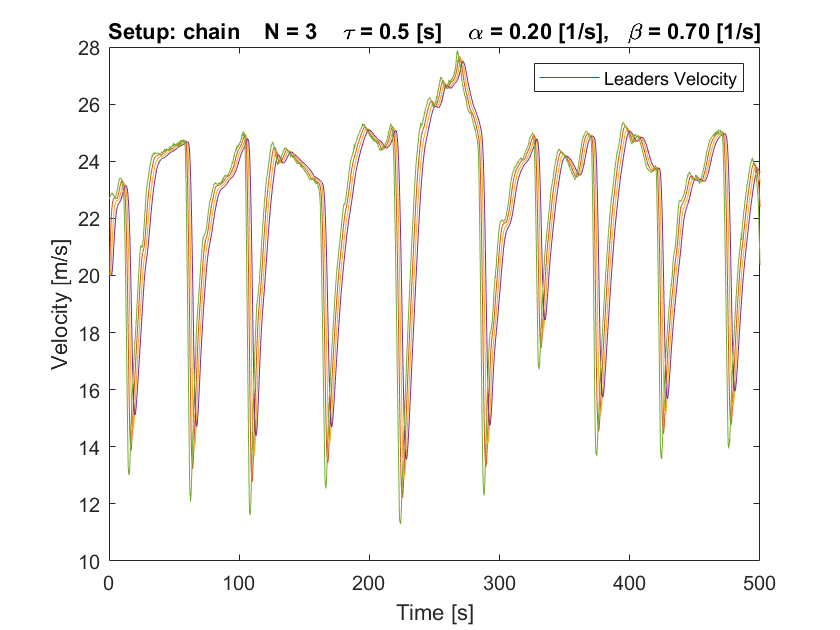

   
   
% plot velocity
figure(3); clf; hold on; box on;
plot(time,vLead);
plot(time,vFollow);
if ~isempty(vLead)
    plot(time,vLead);
end
xlabel('Time [s]');
ylabel('Velocity [m/s]');
title(['Setup: ',vehconfig,'    N = ',num2str(veh_num),'    ',...
       '\tau = ',num2str(tau),' [s]    ',...
       '\alpha = ',num2str(alpha,'%3.2f'),' [1/s],   ',...
       '\beta = ',num2str(beta,'%3.2f'),' [1/s]']);
legend('Leaders Velocity');

function dxdt = OVM(t,x,xtau,time,vLead,vLeadtau,alpha,beta,V)
    % actual and delayed headway and velocity
    hi=x(1:2:end);       
    vi=x(2:2:end);
    hitau=xtau(1:2:end);       
    vitau=xtau(2:2:end);
    % leaders' actual and delayed velocity
    % (each vehicle is leader for the subsequent vehicle)
    if ~isempty(vLead)	% open chain configuration
        viL=[interp1(time,vLead,t,'linear','extrap');...
             vi(1:end-1)];
        viLtau=[interp1(time,vLeadtau,t,'linear','extrap');...
                vitau(1:end-1)];
    else            % ring configuration
        viL=[vi(end);...
             vi(1:end-1)];
        viLtau=[vitau(end);...
                vitau(1:end-1)];
    end
    % optimal velocity model with driver reaction time
    dxdt = [(viL-vi).';(alpha*(V(hitau)-vi)+beta*(viLtau-vitau)).'];
    dxdt = dxdt(:);
end
